Iteration: 1

File 1 - Mean Constant Acceleration: 1.1494 rad/s²


File 1 - Linear Fit Constant Acceleration: 4.8387 rad/s²


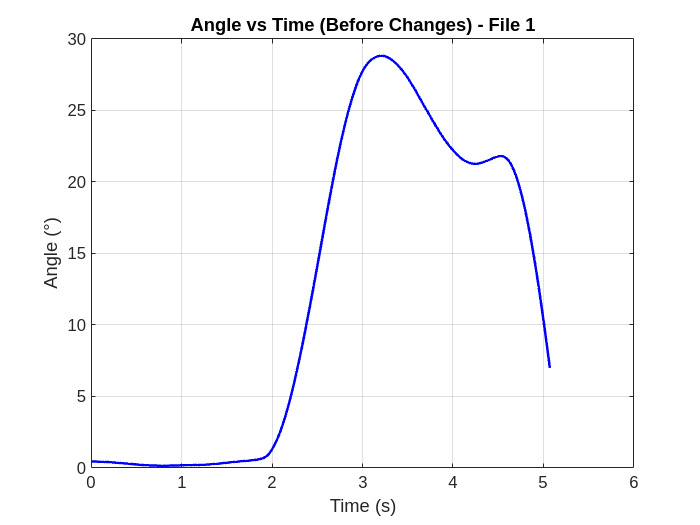

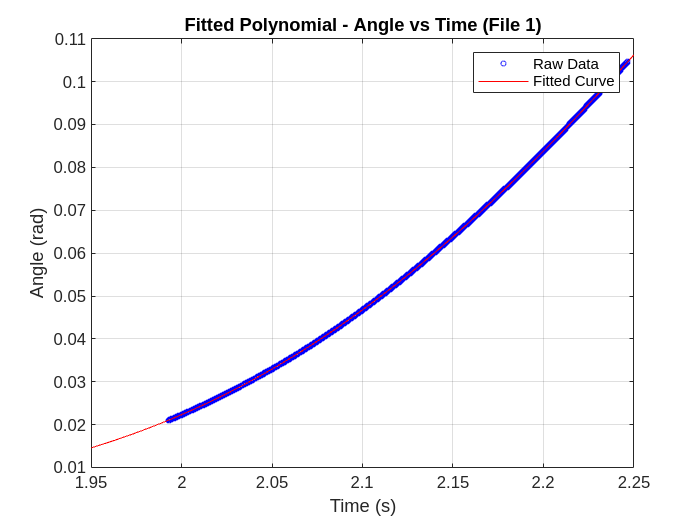

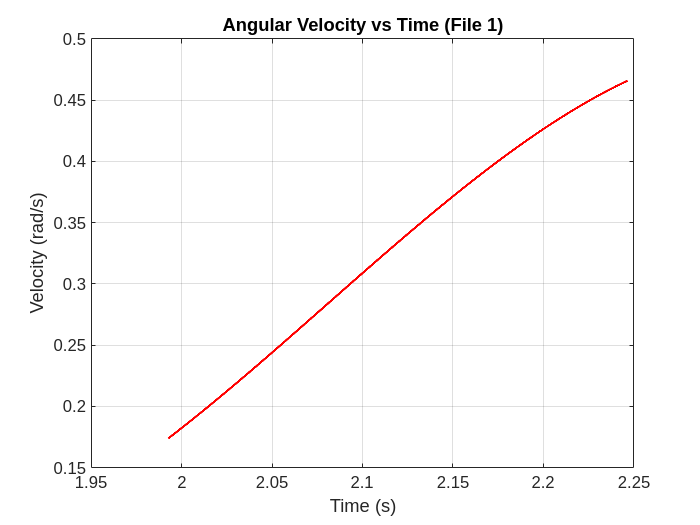

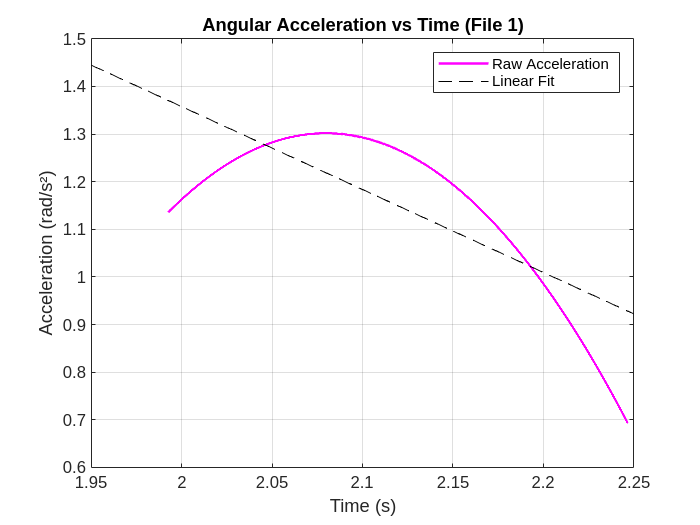

OOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOO

clc; clear; close all;

% Define number of files
num_files = 50;

% Generate file names dynamically
file_names = cell(1, num_files);
for i = 1:num_files
    file_names{i} = sprintf("data_log_3_%d.csv", i);
end

% Directory containing files
data_dir = "/home/amh/Documents/Bachelor/vinkelmaaler_inerti/";

% Initialize arrays to store acceleration results
constant_accelerations_mean = zeros(1, num_files);
constant_accelerations_fit = zeros(1, num_files);

% Loop through each file
for i = 1:1%length(file_names)
    fprintf("Iteration: %d",i)

    % Load data
    data = readtable(fullfile(data_dir, file_names{i}));
    time_before = data.time;
    angle_before = data.angle;
    
    % Define time range filter conditionally for data_log_2_5
    time_range = data.time >= 0.5 & data.time <= 3.0;
    
    % Filter data based on time and angle range
    data = data(time_range & (data.angle >= 1.2 & data.angle <= 6), :);
    
    % Extract time and angle
    time = data.time;
    angle = data.angle;
    
    % Convert angle from degrees to radians
    angle_rad = deg2rad(angle);

    % Step 1: Fit a polynomial to the angle data using `fit()`
    poly_order = 4; % Adjust order based on data shape
    fit_angle = fit(time, angle_rad, sprintf('poly%d', poly_order)); % Fit polynomial of order 4

    % Step 2: Compute first derivative (angular velocity)
    velocity_rad_per_s = differentiate(fit_angle, time); % First derivative
    fit_anglular_vel = fit(time, velocity_rad_per_s, sprintf('poly%d', poly_order)); % Fit polynomial of order 4

    % Step 3: Compute second derivative (angular acceleration) using `gradient()`
    acceleration_rad_per_s2 = differentiate(fit_anglular_vel, time);

    % Step 4: Compute constant acceleration
    % Option 1: Mean acceleration
    constant_acceleration_mean = mean(acceleration_rad_per_s2);
    constant_accelerations_mean(i) = constant_acceleration_mean;

    % Option 2: Linear fit to acceleration data
    acc_fit = fit(time, acceleration_rad_per_s2, 'poly1'); % Linear fit
    constant_acceleration_fit = acc_fit.p2; % Intercept gives constant acceleration
    constant_accelerations_fit(i) = constant_acceleration_fit;

    fprintf("File %d - Mean Constant Acceleration: %.4f rad/s²\n", i, constant_acceleration_mean);
    fprintf("File %d - Linear Fit Constant Acceleration: %.4f rad/s²\n", i, constant_acceleration_fit);

    % Plot Angle vs Time (Before)
    figure;
    plot(time_before, angle_before, 'b', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Angle (°)');
    title(sprintf('Angle vs Time (Before Changes) - File %d', i));
    grid on;


    % Plot Angle vs Time
    figure;
    plot(time, angle_rad, 'bo', 'MarkerSize', 3); hold on;
    plot(fit_angle, 'r-'); % Uses `fit()` directly
    xlabel('Time (s)');
    ylabel('Angle (rad)');
    title(sprintf('Fitted Polynomial - Angle vs Time (File %d)', i));
    legend('Raw Data', 'Fitted Curve');
    grid on;

    % Plot Velocity vs Time
    figure;
    plot(time, velocity_rad_per_s, 'r', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Velocity (rad/s)');
    title(sprintf('Angular Velocity vs Time (File %d)', i));
    grid on;

    % Plot Acceleration vs Time
    figure;
    plot(time, acceleration_rad_per_s2, 'm', 'LineWidth', 1.5); hold on;
    plot(acc_fit, 'k--'); % Uses `fit()` for linear acceleration trend
    xlabel('Time (s)');
    ylabel('Acceleration (rad/s²)');
    title(sprintf('Angular Acceleration vs Time (File %d)', i));
    legend('Raw Acceleration', 'Linear Fit');
    grid on;

    fprintf('OOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOO')

end



% Display all computed constant accelerations
disp('Estimated Constant Accelerations (Mean) for Each File:');

Estimated Constant Accelerations (Mean) for Each File:


disp(constant_accelerations_mean);

    1.1494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



fprintf('Average constant acceleartions (Mean) is %f', mean(constant_accelerations_mean))

Average constant acceleartions (Mean) is 0.022988


disp('Estimated Constant Accelerations (Linear Fit) for Each File:');

Estimated Constant Accelerations (Linear Fit) for Each File:


disp(constant_accelerations_fit);

    4.8387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



fprintf('Average constant acceleartions (Linear Fit) is %f', mean(constant_accelerations_fit))

Average constant acceleartions (Linear Fit) is 0.096774